データのプロット

close;
clear;
clearvars;
figure;
hold on;
dat = readdata("IDVGVB-0.TXT", true);
vg = dat(:, 1);
id = dat(:, 2) * 1e4;
% データをプロット
yyaxis left;
plot(vg, id);
xlabel("V_g [V]");
ylabel("I_d/W [\mum]");

相互コンダクタンス$g_m$を求める

gm = gradient(id) ./ gradient(vg);
yyaxis right;
plot(vg, gm);
ylabel("g_m [mS/\muS]");
vg0 = vg(gm == max(gm))

vg0 = 0.5800

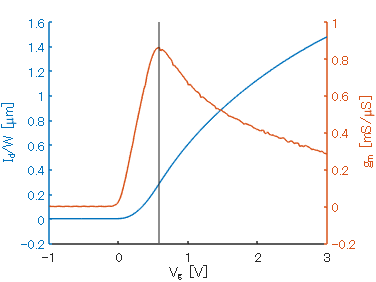

xline(vg0);
hold off;

$g_m$が最大になるのは0.22あたりであることがわかるから、その部分での値を用いる。

$V_{\mathrm{th}} =0\ldotp 22$の部分では

id0 = id(vg == vg0) % peakにおけるId

id0 = 0.2864

grad0 = max(gm);
vth = vg0 - id0 / grad0

vth = 0.2471

次に、SSを求める。

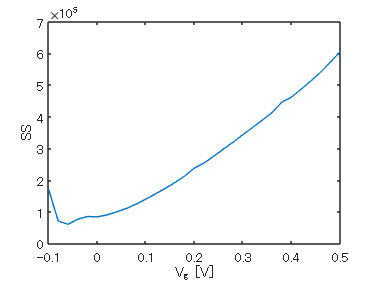

deltaVg = gradient(vg);
deltaLog10Id = gradient(log10(id));
% 複素数になってしまうため
deltaLog10Id = abs(deltaLog10Id);
ss = deltaVg ./ deltaLog10Id * 1e3;
figure;
plot(vg, 1e3 * ss);
xlabel("V_g [V]")
xlim([-0.1, 0.5]);
ylabel("SS")

minSS = min(ss((vg >= -0.1) & (vg <= 0.5)))

minSS = 60.3498

vg_minSS = vg(ss == minSS)

vg_minSS = -0.0600

気温は27℃より低いので、理論値は59.6mV/decadeより小さくなるはず→当日の気温はより低かったので、その値を使って理論値を計算すると良いかも？(例えば20℃の場合の理論値など)